# **3 phase inverter with space vector PWM**

clear all;
close all;

user defined variables

f=50;% fundamental frequency
m=0.85;% modulation index
fs=5000;%switching frequency
Vs=200;% input DC Voltage

Va, Vb, Vc, to Vd, Vq transformation

t=linspace(0,0.02,10000);
Va=sin(2*pi*f*t);
Vb=sin(2*pi*f*t-pi*2/3);
Vc=sin(2*pi*f*t-pi*4/3);
figure;
plot(t,Va);
hold;

Current plot held


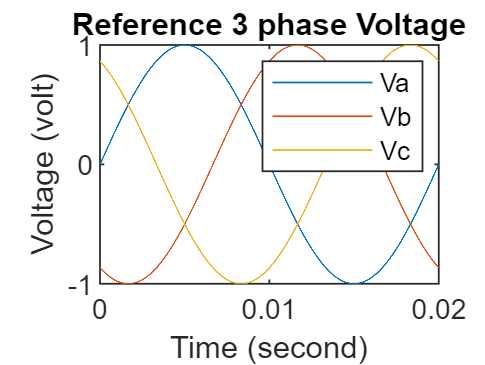

plot(t,Vb);
plot(t,Vc);
title('Reference 3 phase Voltage');
xlabel('Time (second)');
ylabel('Voltage (volt)');
legend('Va','Vb','Vc');

Valpha=(2/3)*Va-(1/3)*Vb-(1/3)*Vc;
Vbeta=(1/sqrt(3))*(Vb-Vc);
figure;
plot(t,Valpha);
hold;

Current plot held


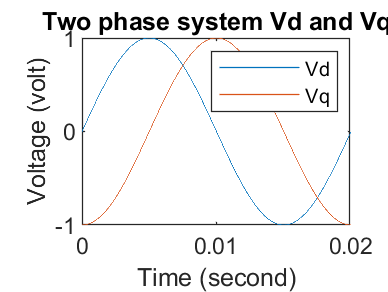

plot(t,Vbeta);
title('Two phase system Vd and Vq');
xlabel('Time (second)');
ylabel('Voltage (volt)');
legend('Vd', 'Vq');

Vd, Vq to Vref, alpha transformation

Vref=abs(Valpha+1j*Vbeta);
ang=angle(Valpha+1j*Vbeta)*180/pi;
for n=1:10000
    if ang(n)<0
        ang(n)=ang(n)+360;
    end
end
ang(10000)=0;

Sector number calculation

n=floor(ang/60)+1;

calculating T0, T1,T2

Ts=1/fs;
T1=m*Ts*[sin((n*pi/3)-(ang*pi/180))]/(sin(pi/3));
T2=m*Ts*[sin((ang*pi/180)-((n-1)*pi/3))]/(sin(pi/3));
T0=Ts-T1-T2;
figure;
plot(t,T0);
hold;

Current plot held


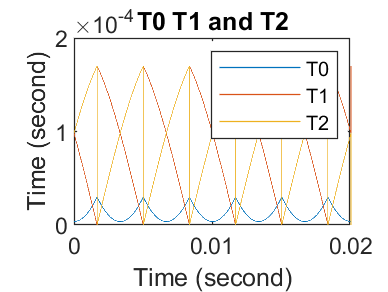

plot(t,T1);
plot(t,T2);
title('T0 T1 and T2');
xlabel('Time (second)');
ylabel('Time (second)');
legend('T0','T1','T2');

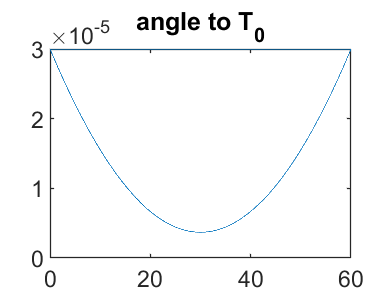

figure;
ang1=[];
for i = 1:5000
    T01(i)=T0(i);
    ang1(i)=ang(i);
end   
plot(ang1,T01);
xlim([0,60]);
title('angle to T_{0}');

Calculating duty cycle of high side switches corresponding to sector

D_S1=[]; D_S3=[]; D_S5=[];
for k=1:10000
    if n(k)==1
        D_S1=[D_S1,(T1(k)+T2(k)+T0(k)/2)/Ts];
        D_S3=[D_S3,(T2(k)+T0(k)/2)/Ts];
        D_S5=[D_S5,(T0(k)/2)/Ts];
    end
    if n(k)==2
        D_S1=[D_S1,(T1(k)+T0(k)/2)/Ts];
        D_S3=[D_S3,(T1(k)+T2(k)+T0(k)/2)/Ts];
        D_S5=[D_S5,(T0(k)/2)/Ts];
    end
    if n(k)==3
        D_S1=[D_S1,(T0(k)/2)/Ts];
        D_S3=[D_S3 , (T1(k)+T0(k)/2)/Ts];
        D_S5=[D_S5 , (T1(k)+T2(k)+T0(k)/2)/Ts];
    end
     if n(k)==4
        D_S1=[D_S1 , (T0(k)/2)/Ts];
        D_S3=[D_S3 , (T1(k)+T0(k)/2)/Ts];
        D_S5=[D_S5 , (T1(k)+T2(k)+T0(k)/2)/Ts];
    end
    if n(k)==5
        D_S1=[D_S1 , (T2(k)+T0(k)/2)/Ts];
        D_S3=[D_S3 , (T0(k)/2)/Ts];
        D_S5=[D_S5 , (T1(k)+T2(k)+T0(k)/2)/Ts];
    end
    if n(k)==6
        D_S1=[D_S1 , (T1(k)+T2(k)+T0(k)/2)/Ts];
        D_S3=[D_S3 , (T0(k)/2)/Ts];
        D_S5=[D_S5 , (T1(k)+T0(k)/2)/Ts];
    end
end

figure;
plot(t,D_S1);
hold;

Current plot held


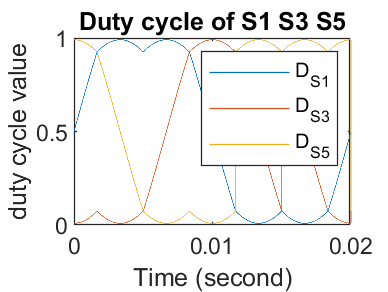

plot(t,D_S3);
plot(t,D_S5);
title('Duty cycle of S1 S3 S5');
xlabel('Time (second)');
ylabel('duty cycle value');
legend('D_{S1}','D_{S3}','D_{S5}');

D_S1=(D_S1-0.5)*2;
D_S3=(D_S3-0.5)*2;
D_S5=(D_S5-0.5)*2;

Generating reference sawtooth waveform of 5KHz

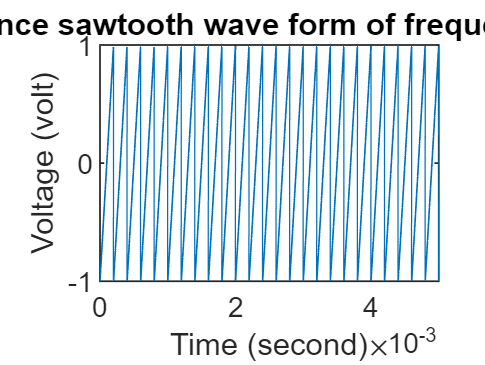

ref_signal= sawtooth(2*pi*fs*t);
figure;
plot(t,ref_signal);
axis([0 0.005 -1 1]);
title('Reference sawtooth wave form of frequency 5KHz');
xlabel('Time (second)');
ylabel('Voltage (volt)');

Comparing duty cycle with the reference sawtooth waveform

PWM_S1=D_S1>ref_signal;
PWM_S3=D_S3>ref_signal;
PWM_S5=D_S5>ref_signal;

Taking not of gate signal of high side switches

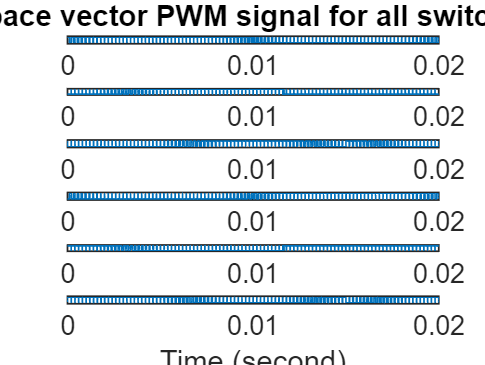

PWM_S2=~PWM_S5;
PWM_S4=~PWM_S1;
PWM_S6=~PWM_S3;
figure;
subplot(6,1,1);
plot(t,PWM_S1);
ylim([-0.2 1.2]);
title('Space vector PWM signal for all switches');
ylabel('Vg 1');
subplot(6,1,2);
plot(t,PWM_S2);
ylim([-0.2 1.2]);
ylabel('Vg 2');
subplot(6,1,3);
plot(t,PWM_S3);
ylim([-0.2 1.2]);
ylabel('Vg 3');
subplot(6,1,4);
plot(t,PWM_S4);
ylim([-0.2 1.2]);
ylabel('Vg 4');
subplot(6,1,5);
plot(t,PWM_S5);
ylim([-0.2 1.2]);
ylabel('Vg 5');
subplot(6,1,6);
plot(t,PWM_S6);
ylim([-0.2 1.2]);
ylabel('Vg 6');
xlabel('Time (second)');

3 phase inverter implementation

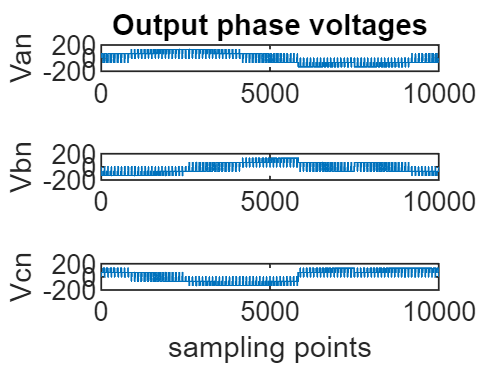

Van=[];Vbn=[];Vcn=[];
Vab=[];Vbc=[];Vca=[];
for k=1:10000
    if (PWM_S1(k)==1 && PWM_S3(k)==0 && PWM_S5(k)==1)
        Van=[Van, Vs/3];
        Vbn=[Vbn,-2*Vs/3];
        Vcn=[Vcn,Vs/3];
        Vab=[Vab,Vs];
        Vbc=[Vbc,-Vs];
        Vca=[Vca,0];
    end
    if (PWM_S1(k)==1 && PWM_S3(k)==0 && PWM_S5(k)==0)
        Van=[Van, 2*Vs/3];
        Vbn=[Vbn, -Vs/3];
        Vcn=[Vcn, -Vs/3];
        Vab=[Vab, Vs];
        Vbc=[Vbc, 0];
        Vca=[Vca, -Vs];
    end
    if (PWM_S1(k)==1 && PWM_S3(k)==1 && PWM_S5(k)==0)
        Van=[Van, Vs/3];
        Vbn=[Vbn, Vs/3];
        Vcn=[Vcn, -2*Vs/3];
        Vab=[Vab, 0];
        Vbc=[Vbc, Vs];
        Vca=[Vca, -Vs];
    end
 if (PWM_S1(k)==0 && PWM_S3(k)==1 && PWM_S5(k)==0)
        Van=[Van, -Vs/3];
        Vbn=[Vbn, 2*Vs/3];
        Vcn=[Vcn, -Vs/3];
        Vab=[Vab, -Vs];
        Vbc=[Vbc, Vs];
        Vca=[Vca, 0];
 end
 if (PWM_S1(k)==0 && PWM_S3(k)==1 && PWM_S5(k)==1)
        Van=[Van, -2*Vs/3];
        Vbn=[Vbn, Vs/3];
        Vcn=[Vcn, Vs/3];
        Vab=[Vab, -Vs];
        Vbc=[Vbc, 0];
        Vca=[Vca, Vs];
 end
 if (PWM_S1(k)==0 && PWM_S3(k)==0 && PWM_S5(k)==1)
        Van=[Van , -Vs/3];
        Vbn=[Vbn , -Vs/3];
        Vcn=[Vcn , 2*Vs/3];
        Vab=[Vab , 0];
        Vbc=[Vbc , -Vs];
        Vca=[Vca , Vs];
    end
if (PWM_S1(k)==0 && PWM_S3(k)==0 && PWM_S5(k)==0)
    Van=[Van , 0];
        Vbn=[Vbn , 0];
        Vcn=[Vcn , 0];
        Vab=[Vab , 0];
        Vbc=[Vbc , 0];
        Vca=[Vca , 0];
end
if (PWM_S1(k)==1 && PWM_S3(k)==1 && PWM_S5(k)==1)
        Van=[Van , 0];
        Vbn=[Vbn , 0];
        Vcn=[Vcn , 0];
        Vab=[Vab , 0];
        Vbc=[Vbc , 0];
        Vca=[Vca , 0];
end
end
figure;
subplot(3,1,1);
plot(Van);
title('Output phase voltages');
ylabel('Van');
subplot(3,1,2);
plot(Vbn);
ylabel('Vbn');
subplot(3,1,3);
plot(Vcn);
ylabel('Vcn');
xlabel('sampling points');

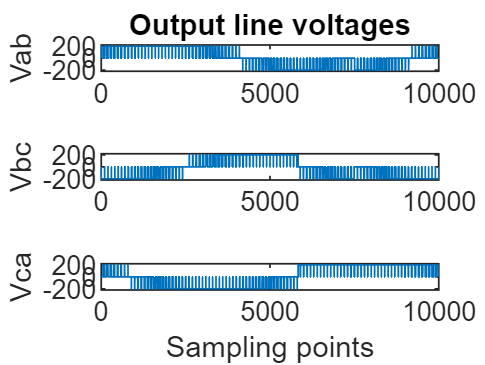


figure;
subplot(3,1,1);
plot(Vab);
ylim([-Vs-20 Vs+20]);
ylabel('Vab');
title('Output line voltages');
ylabel('Vab');
subplot(3,1,2);
plot(Vbc);
ylim([-Vs-20 Vs+20]);
ylabel('Vbc');
subplot(3,1,3);
plot(Vca);

ylim([-Vs-20 Vs+20]);
xlabel('Sampling points');
ylabel('Vca');